# Lab 2

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

## 1  Difference operators

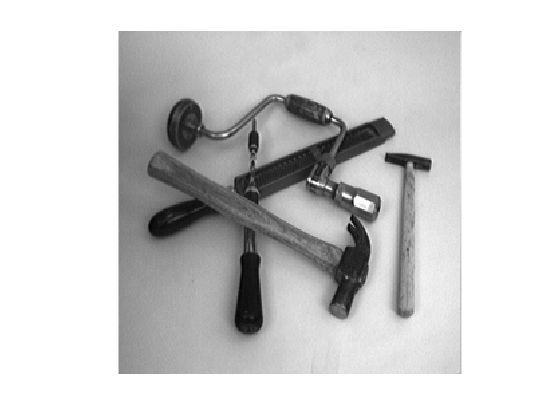

deltax = 0.5*[-1,0,1];
deltay = 0.5*[-1;0;1];

tools = few256;
showgrey(tools);

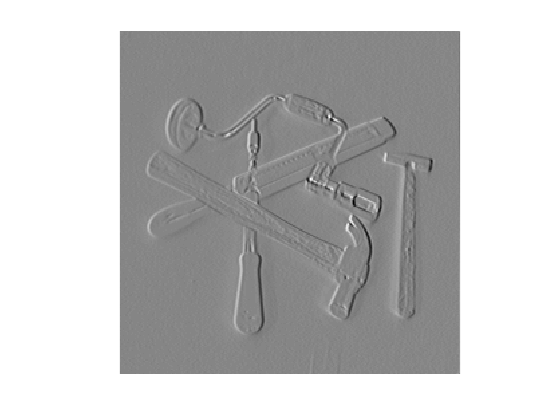

dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools);

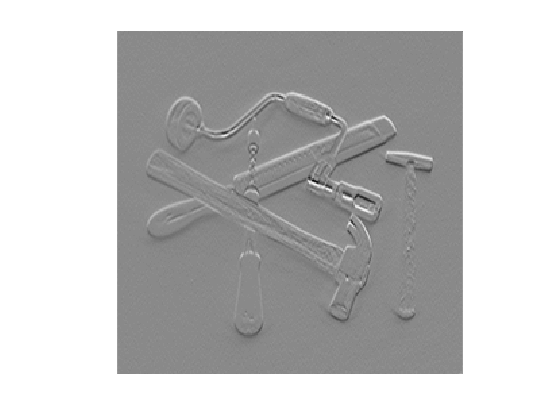

dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)

## 2  Point–wise thresholding of gradient magnitudes

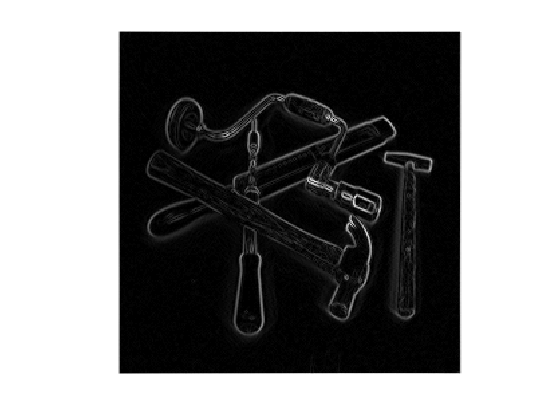

dxtools = conv2(tools, deltax, 'same');
dytools = conv2(tools, deltay, 'same');

gradmagntools = sqrt(dxtools .^2 + dytools .^2);
showgrey(gradmagntools)

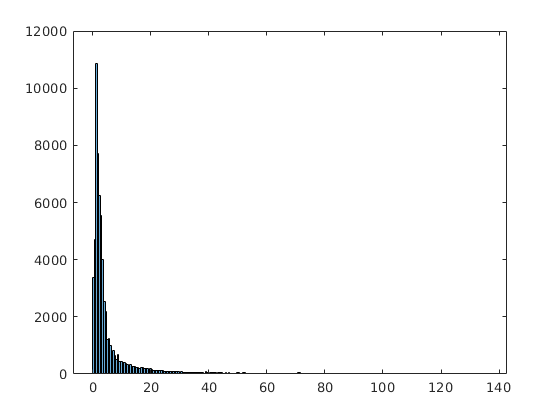

histogram(gradmagntools,256);

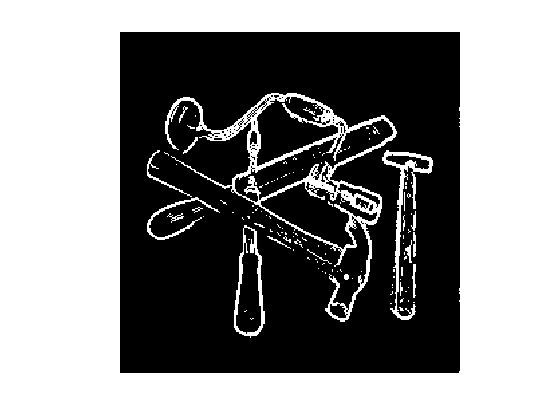

%set(gca, 'YScale', 'log')

showgrey((gradmagntools - 18) > 0)

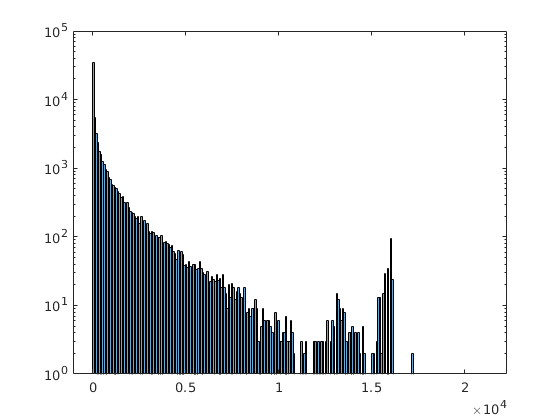

img = godthem256;
M = Lv(img);


histogram(M,256);
set(gca, 'YScale', 'log')

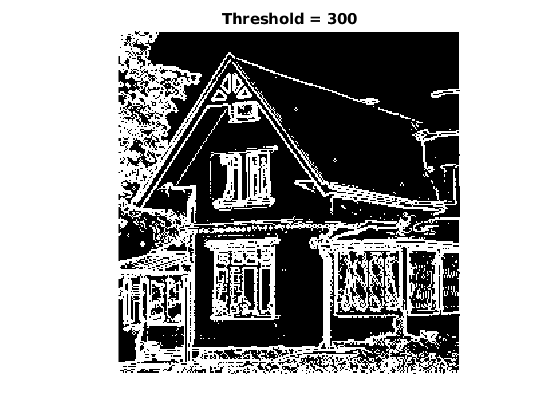

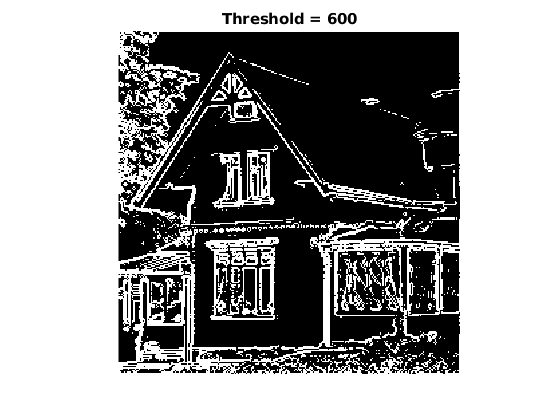

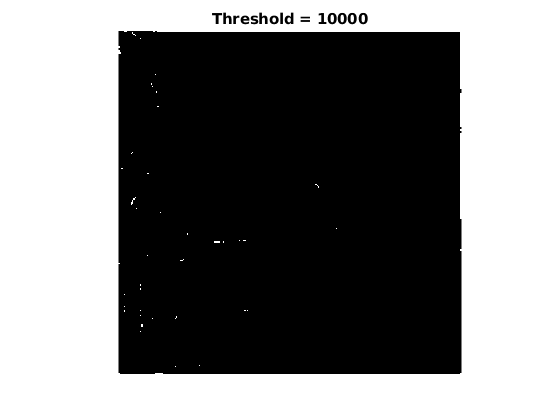


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

with smoothing

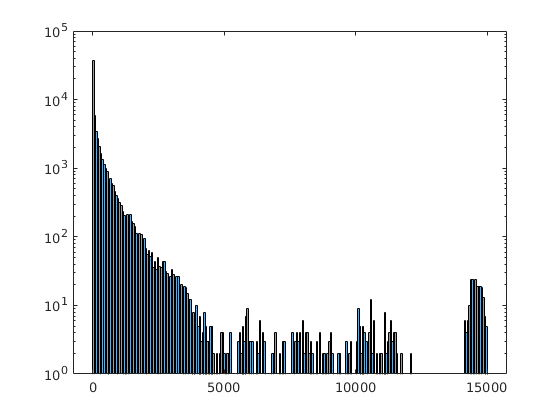

img = discgaussfft(godthem256,1);
M = Lv(img);


histogram(M,256);
set(gca, 'YScale', 'log')

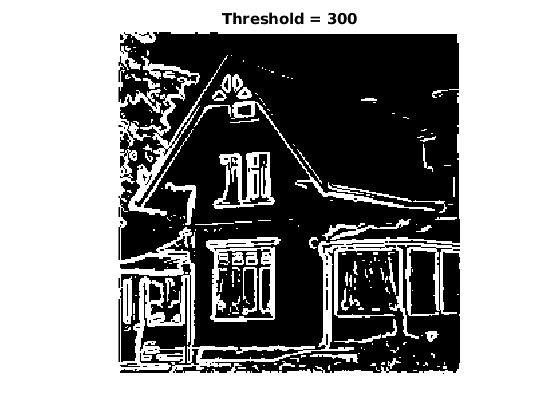

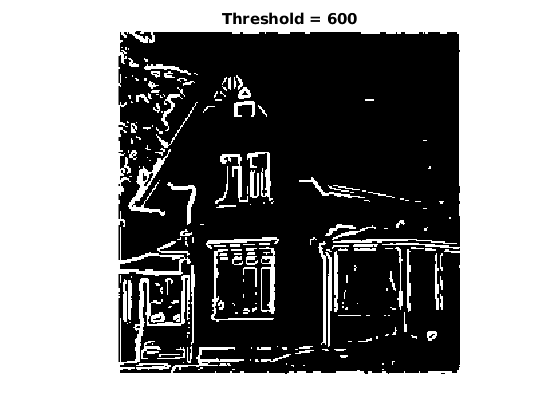

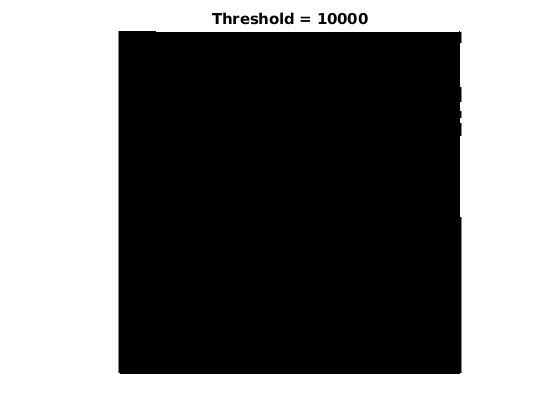


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

## 4  Computing differential geometry descriptors

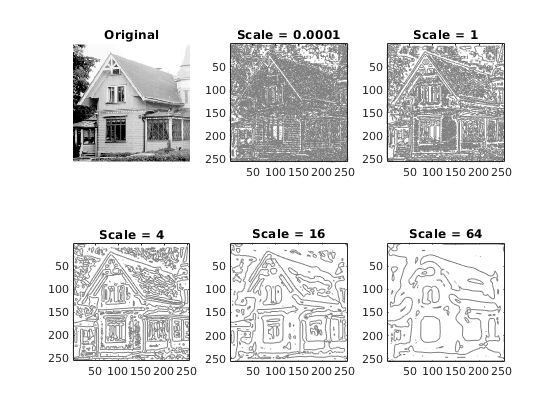

house = godthem256;
figure();

subplot(2,3,1);
showgrey(house);
title("Original")

idx = 2;
for scale = [0.0001 1.0 4.0 16.0 64.0]
    subplot(2,3,idx);
    contour(Lvvtilde(discgaussfft(house, scale )), [0 0]);
    title(sprintf("Scale = %g", scale));
    axis('image')
    axis('ij')
    idx = idx + 1;
end

saveas(gcf,'question4.svg')

Now let's see the third derivative

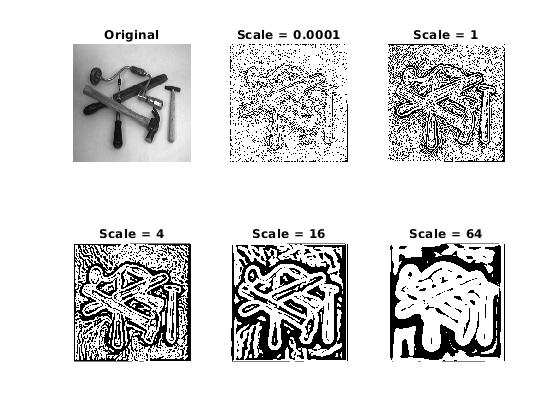

figure('DefaultAxesPosition', [0.1, 0.1, 0.8, 0.8]);
tools = few256;
subplot(2,3,1);
showgrey(tools);
title("Original");

idx = 2;
for scale = [0.0001 1.0 4.0 16.0 64.0]
    h = subplot(2,3,idx);
    showgrey(Lvvvtilde(discgaussfft(tools, scale)) < 0)
    title(sprintf("Scale = %g", scale));
    axis('image');
    axis('ij');
    idx = idx + 1;
end

saveas(gcf,'question5.svg')

## 5  Extraction of edge segments

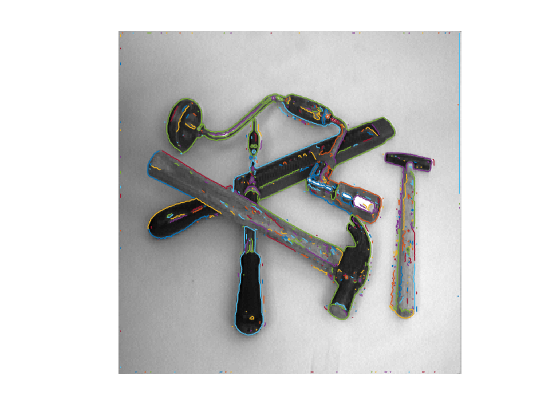

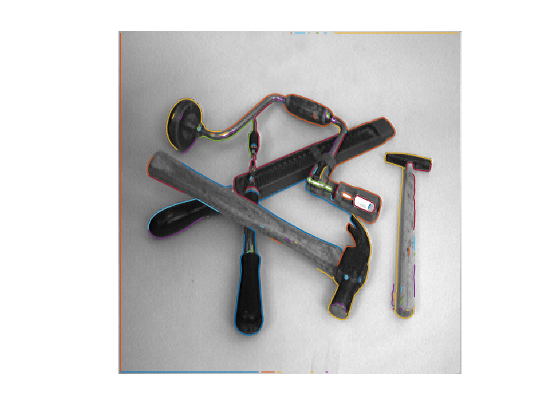

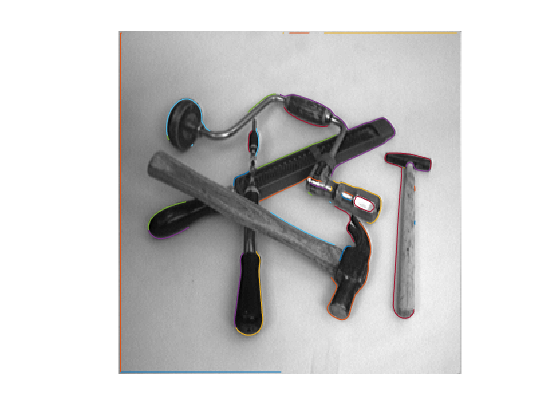

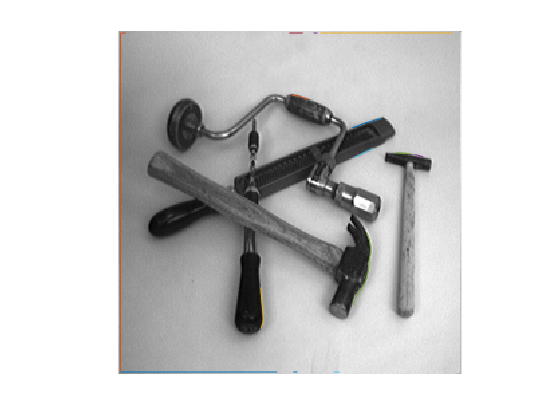

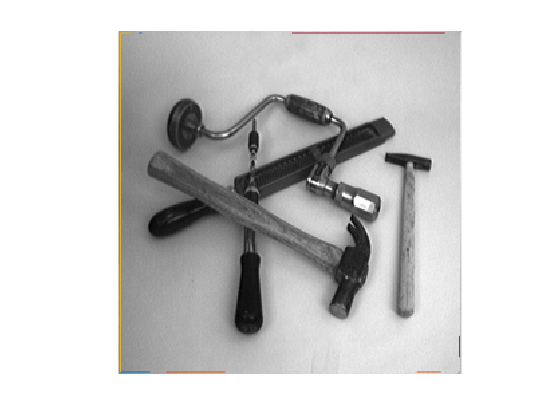

tools = few256;
warning ('off','all');
for scale = [0.0001 1.0 4.0 16.0 64.0]
    figure();
    curves = extractedge(tools,scale, 200, 'same');
    overlaycurves(tools, curves);

end

## 6  Hough transform

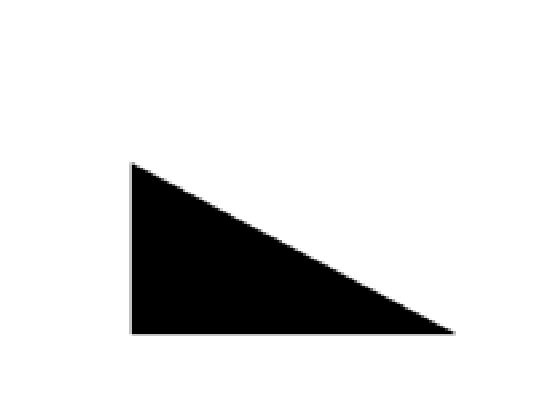

%warning ('off','all');
testimage1 = triangle128;

smalltest1 = binsubsample(testimage1);

curves = extractedge(testimage1,scale, 200, 'same');
overlaycurves(testimage1, curves);

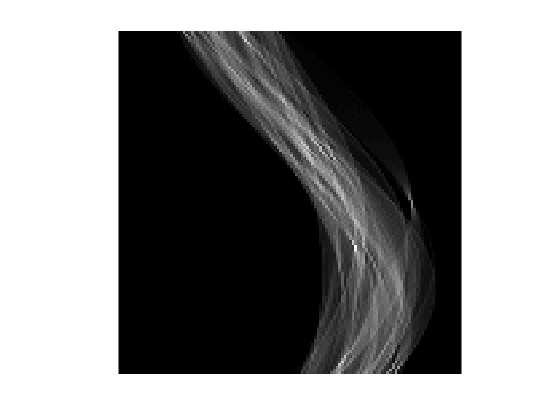

curves =          0    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000   50.0000
  120.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000

  252.0286

   718

Image size is 256


figure();


[a,b] = houghedgeline(tools,10,10,128,128,80,true);

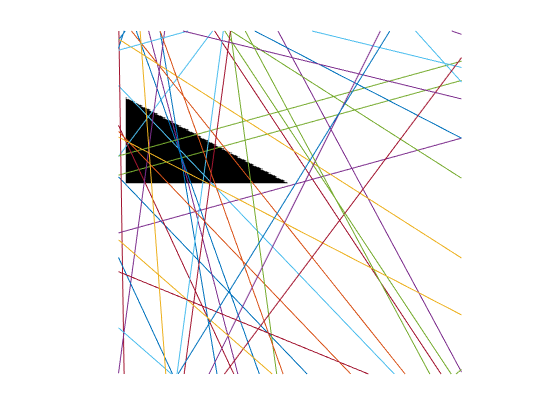


edges = [];

for i = 1 : size(a,1)
    
    rho = a(i,1);
    theta = a(i,2);
    if(abs(rho) < 1)
        continue;
    end
    x0 = (rho)/cosd(theta);
    y0 = 0;
    dy = 300 ;
    dx = - dy * sin(theta)/cos(theta);
    
    
    edges = [edges;0,3;y0,x0;(y0 + dy),(x0 + dx);(y0 - dy),(x0 - dx)];
end


overlaycurves(testimage1, edges');
axis([0 256 0 256])